# Example: COVID-2019 data for an entire Country

I am taking some data from John Hopkins university [1]

[1] [https://github.com/CSSEGISandData/COVID-19](https://github.com/CSSEGISandData/COVID-19)

## Initialisation

The parameters are here taken as constant except the death rate and the cure rate.

clearvars;close all;clc;
% Download the data from ref [1] and read them with the function getDataCOVID
[tableConfirmed,tableDeaths,tableRecovered,time] = getDataCOVID();
% time = time(1:end-1);
fprintf(['Most recent update: ',datestr(time(end)),'\n'])

Most recent update: 18-May-2021


Location = 'United Arab Emirates';
try
    indR = find(contains(tableRecovered.CountryRegion,Location)==1 & (tableRecovered.ProvinceState.ismissing()==1))
    indC = find(contains(tableConfirmed.CountryRegion,Location)==1 & (tableConfirmed.ProvinceState.ismissing()==1))
    indD = find(contains(tableDeaths.CountryRegion,Location)==1 & (tableDeaths.ProvinceState.ismissing()==1))
catch exception
    searchLoc = strfind(tableRecovered.CountryRegion,Location);
    indR = find(~cellfun(@isempty,searchLoc)) ; 
    
    searchLoc = strfind(tableConfirmed.CountryRegion,Location);
    indC = find(~cellfun(@isempty,searchLoc)) ; 
    
    searchLoc = strfind(tableDeaths.CountryRegion,Location);
    indD = find(~cellfun(@isempty,searchLoc));    
end

indR = 240

indC = 255

indD = 255


disp(tableRecovered(indR,1:2))

    ProvinceState        CountryRegion     
    _____________    ______________________

      <missing>      "United Arab Emirates"



disp(tableConfirmed(indC,1:2))

    ProvinceState        CountryRegion     
    _____________    ______________________

      <missing>      "United Arab Emirates"



disp(tableDeaths(indD,1:2))

    ProvinceState        CountryRegion     
    _____________    ______________________

      <missing>      "United Arab Emirates"




indR = indR(1);
indD = indD(1);
indC = indC(1);

Recovered = table2array(tableRecovered(indR,5:end));
Deaths = table2array(tableDeaths(indD,5:end));
Confirmed = table2array(tableConfirmed(indC,5:end));
% If the number of confirmed cases is small, it is difficult to know whether
% the quarantine has been rigorously applied or not. In addition, this
% suggests that the number of infectious is much larger than the number of
% confirmed cases

## Choose Initial and final time

tStart = datetime(2021,1,16);
tEnd = datetime(2021,3,1);
indT = find(time>=tStart & time <=tEnd);
Recovered=Recovered(indT);
Deaths = Deaths(indT);
time = time(indT);
Confirmed = Confirmed(indT);

if isempty(Confirmed)
    warning('"Confirmed" is an empty array. Check the value of "minNum". Computation aborted.')
    return
end

Npop= 1e7; % population

## Fitting of the generalized SEIR model to the real data

% Definition of the first estimates for the parameters
alpha_guess = 0.06; % protection rate
beta_guess = 1.0; % Infection rate
LT_guess = 5; % latent time in days
Q_guess = 0.1; % rate at which infectious people enter in quarantine
lambda_guess = [0.01,0.001,10]; % recovery rate
kappa_guess = [0.001,0.001,10]; % death rate

guess = [alpha_guess,...
    beta_guess,...
    1/LT_guess,...
    Q_guess,...
    lambda_guess,...
    kappa_guess];


% Initial conditions
Q0 = Confirmed(1)-Recovered(1)-Deaths(1);
I0 = 0.3*Q0; % Initial number of infectious cases. Unknown but unlikely to be zero.
E0 = 0.3*Q0; % Initial number of exposed cases. Unknown but unlikely to be zero.
R0 = Recovered(1);
D0 = Deaths(1);

Active = Confirmed-Recovered-Deaths;
Active(Active<0) = 0; % No negative number possible
[alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,lambdaFun,kappaFun] = ...
    fit_SEIQRDP(Active,Recovered,Deaths,Npop,E0,I0,time,guess);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0         11      8.6976e+12                      2.85e+14
     1         22      1.2326e+12       0.352704       3.76e+13      
     2         33     1.62688e+11        0.32117       5.29e+12      
     3         44     1.47852e+10       0.236301       7.53e+11      
     4         55      1.8625e+09      0.0958529       7.86e+10      
     5         66     1.48428e+09       0.704172       7.29e+09      
     6         77     1.48428e+09        1.13274       7.29e+09      
     7         88     1.45532e+09       0.283185       3.25e+10      
     8         99     1.35945e+09      0.0707961       1.84e+09      
     9        110     1.21515e+09       0.141592       1.59e+10      
    10        121     1.11606e+09       0.283185       5.55e+09      
    11        132     1.11606e+09       0.566369       5.55e+09      
    12        143     1.01916e+0

## Simulate the epidemy outbreak based on the fitted parameters

dt = 1/24; % time step
time1 = datetime(time(1), 'Locale', 'en_US'):dt:datetime(time(end)+datenum(45), 'Locale', 'en_US');
N = numel(time1);
t = [0:N-1].*dt;
Alpha2=0.1

Alpha2 = 0.1000

[S,E,I,Q,R,D,P] = SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,...
    Npop,E0,I0,Q0,R0,D0,t,lambdaFun,kappaFun);

## Display the fitted and measured death and recovery rates

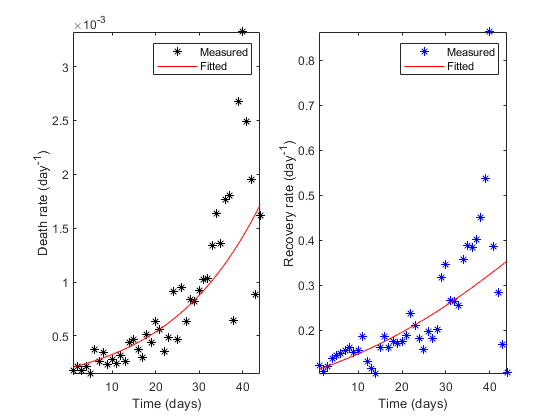

checkRates(time,Active,Recovered,Deaths,kappaFun,lambdaFun,Kappa1,Lambda1);

## Comparison of the fitted and real data

Active cases = Confirmed-Deaths-Recovered (database) = Quarantined (SEIQRDP model)

clf;close all;
figure
%semilogy(time1,Q,'r',time1,R,'b',time1,D,'k');
hold on
semilogy(time,Active,'r--',time,Recovered,'b--',time,Deaths,'k--');
% ylim([0,1.1*Npop])
ylabel('Number of cases')
xlabel('time (days)')
leg = {'Active (fitted)',...
        'Recovered (fitted)','Deceased (fitted)',...
        'Active (reported)','Recovered (reported)','Deceased  (reported)'};
legend(leg{:},'location','southoutside')

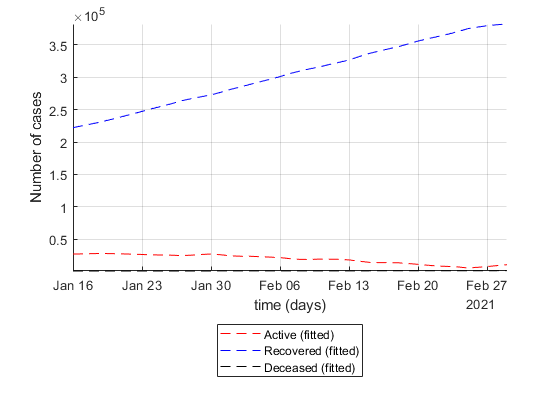

set(gcf,'color','w')
grid on
axis tight
 set(gca,'yscale','lin') 